color threshold 

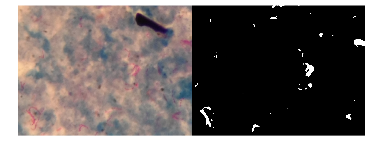

testthresh = createMask(test1);
imshowpair(test1, testthresh, "montage")

display

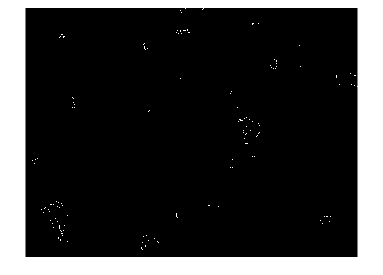

edge1 = edge(testthresh);
imshow(edge1)

test1

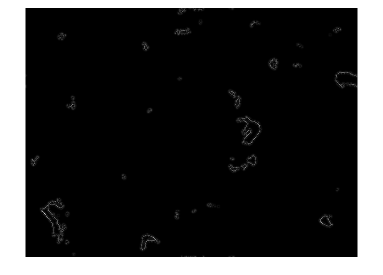

saliency =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

ballness =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

orientation =     1.0998    1.2114    1.4483   -0.7854    1.1630    1.2490    1.3390   -0.7854    1.5708   -0.7854         0         0         0    0.3927    1.5708    0.9079    0.7854    1.5708    1.1781   -0.7854   -0.0927    1.4483         0   -0.7854   -0.7854    1.1397    0.7854   -0.2450   -1.2768    1.4618    1.0172    0.8352   -1.3390    1.3914   -0.2940    0.6629   -0.5536   -0.4914   -0.7854         0    0.0826    0.7854    1.0556    1.2768    1.3390   -1.4153   -1.0731   -1.3068   -1.3006   -1.1781
    1.5500   -1.1228    1.2490    0.7854    1.1228    0.7854    0.2318    1.2490    0.7854    0.7854    0.7854    0.7854    1.1781    0.7854    1.1781   -1.2861    1.5708         0   -1.0172         0    0.2793   -1.5086   -1.0172    1.5708    1.5708   -1.1781   -1.0794   -0.6629    0.8228    0.5792    0.8988   -0.3927    1.0794    1.4882    1.5708    1.5708   -0.7854   -1.4882    1.5708    1.4483    0.9463    0.7854    1.1228    1.0450    1.1397    0.7854    1.2153    0.9648   -1

[s, o]= encode(edge1);
[saliency,ballness,orientation] = vote(s, o, 5)